Abs = ABS.Data;
n = length(Abs);
t = 0:0.01:0.01*(n-1);


## Fx tracking

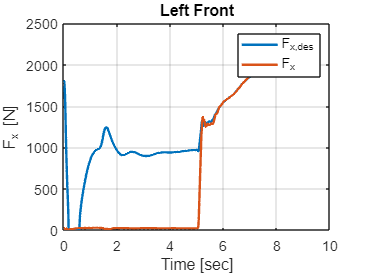

fx_lf = Fxc_lf.Data;
figure(1); clf;
plot(t,fx_lf,'LineWidth',2);grid on;
title("Left Front");
legend("F_{x,des}","F_x","Fontsize",12);xlabel("Time [sec]");ylabel("F_x [N]");
set(gca,"Fontsize",12); xlim([0 10]);ylim([0 2500])

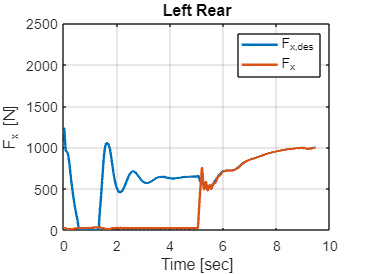


fx_lr = Fxc_lr.Data;
figure(2); clf;
plot(t,fx_lr,'LineWidth',2);grid on;
title("Left Rear");
legend("F_{x,des}","F_x","Fontsize",12);xlabel("Time [sec]");ylabel("F_x [N]");
set(gca,"Fontsize",12); xlim([0 10]);ylim([0 2500])

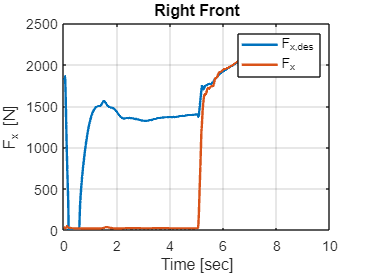

fx_rf = Fxc_rf.Data;
figure(3); clf;
plot(t,fx_rf,'LineWidth',2);grid on;
title("Right Front");
legend("F_{x,des}","F_x","Fontsize",12);xlabel("Time [sec]");ylabel("F_x [N]");
set(gca,"Fontsize",12); xlim([0 10]);ylim([0 2500])

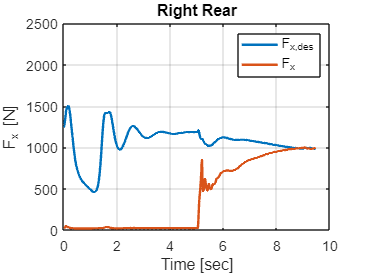


fx_rr = Fxc_rr.Data;
figure(4); clf;
plot(t,fx_rr,'LineWidth',2);grid on;
title("Right Rear");
legend("F_{x,des}","F_x","Fontsize",12);xlabel("Time [sec]");ylabel("F_x [N]");
set(gca,"Fontsize",12); xlim([0 10]);ylim([0 2500])

## ABS

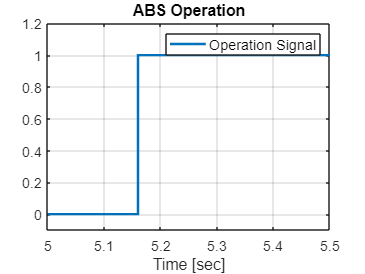

figure(5); clf;
stairs(t,Abs,'LineWidth',2);grid on;
title("ABS Operation");
legend("Operation Signal","Fontsize",12);xlabel("Time [sec]");
set(gca,"Fontsize",12); xlim([5 5.5]);ylim([-0.1 1.2])

## Input

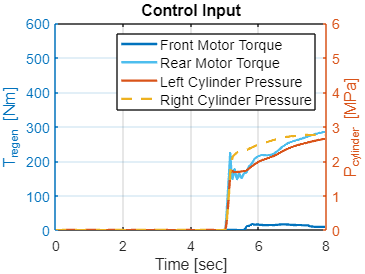

tqin = Trq_in.Data;
pc = Pc.Data;
figure(6); clf;
yyaxis left
plot(t,tqin(:,1),'LineWidth',2,'Color','#0072BD');grid on;hold on;
plot(t,tqin(:,2),'-','LineWidth',2,'Color','#4DBEEE');grid on;
ylabel("T_{regen} [Nm]");ylim([0 600]);
yyaxis right
plot(t,pc(:,1),'LineWidth',2,'Color','#D95319');grid on;hold on;
plot(t,pc(:,2),'LineWidth',2,'Color','#EDB120');grid on;
ylabel("P_{cylinder} [MPa]");ylim([0 6]);



title("Control Input");
legend("Front Motor Torque","Rear Motor Torque","Left Cylinder Pressure","Right Cylinder Pressure","Fontsize",12);xlabel("Time [sec]");
set(gca,"Fontsize",12); xlim([0 8])

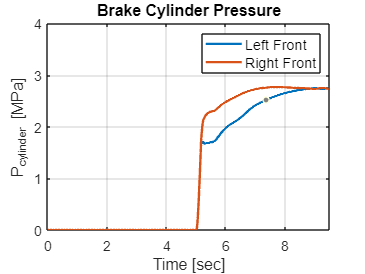



figure(7); clf;
plot(t,pc,'LineWidth',2);grid on;
title("Brake Cylinder Pressure");
legend("Left Front","Right Front","Fontsize",12);xlabel("Time [sec]");ylabel("P_{cylinder} [MPa]");
set(gca,"Fontsize",12); xlim([0 9.5]);ylim([0 4]);

## gain

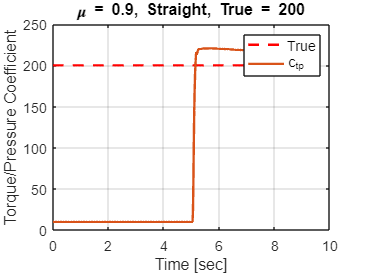

k = kappa.Data;
figure(8); clf;
ref = 200*ones(1,n);
plot(t,ref,'--r','LineWidth',2);hold on;
plot(t,k,'LineWidth',2);grid on;
title("\mu = 0.9, Straight, True = 200");
legend("True","c_{tp}","Fontsize",12);xlabel("Time [sec]");ylabel("Torque/Pressure Coefficient");
set(gca,"Fontsize",12); xlim([0 10]);ylim([0 250]);

## Comparision

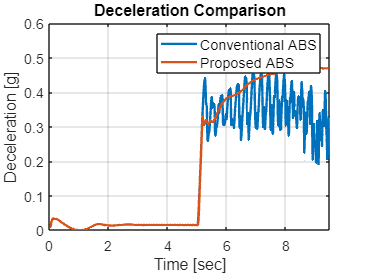

ax_conv = Ax_conv.Data;
slip_conv = Slip_conv.Data;
ax_pro = Ax_pro.Data;
slip_pro = Slip_pro.Data;
n = length(ax_pro(:,1));
figure(8); clf;
plot(t(1:n),-ax_conv(1:n),'LineWidth',2);grid on;hold on;
plot(t(1:n),-ax_pro(1:n)/9.8,'LineWidth',2);
title("Deceleration Comparison");
legend("Conventional ABS","Proposed ABS","Fontsize",12);xlabel("Time [sec]");ylabel("Deceleration [g]");
set(gca,"Fontsize",12); xlim([0 9.5]);ylim([0 0.6])

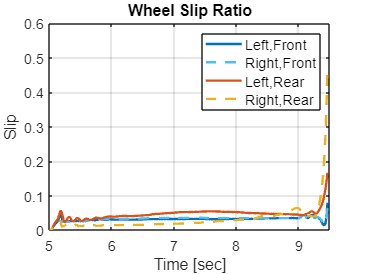


figure(9); clf;
% plot(t(1:n),slip_conv(1:n,1),'LineWidth',1,'Color','#0072BD');
% plot(t(1:n),slip_conv(1:n,2),'LineWidth',1,'Color','#4DBEEE');
plot(t(1:n),-slip_pro(1:n,1),'LineWidth',2,'Color','#0072BD');grid on;hold on;
plot(t(1:n),-slip_pro(1:n,3),'--','LineWidth',2,'Color','#4DBEEE');
plot(t(1:n),-slip_pro(1:n,2),'LineWidth',2,'Color','#D95319');
plot(t(1:n),-slip_pro(1:n,4),'--','LineWidth',2,'Color','#EDB120');
title("Wheel Slip Ratio");
legend("Left,Front","Right,Front","Left,Rear","Right,Rear","Fontsize",12);xlabel("Time [sec]");ylabel("Slip");
set(gca,"Fontsize",12); xlim([5 9.5]);ylim([0 0.6])

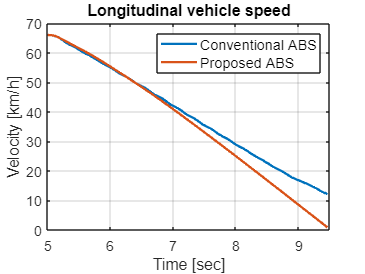


v_conv = V_conv.Data;
v_pro = V.Data;
n = length(ax_pro(:,1));
figure(10); clf;
plot(t(1:n),v_conv(1:n),'LineWidth',2);grid on;hold on;
plot(t(1:n),v_pro(1:n),'LineWidth',2);
title("Longitudinal vehicle speed");
legend("Conventional ABS","Proposed ABS","Fontsize",12);xlabel("Time [sec]");ylabel("Velocity [km/h]");
set(gca,"Fontsize",12); xlim([5 9.5]);ylim([0 70])

jerk_conv = (-ax_conv(501:n-50)+ax_conv(500:n-51))*100;
jerk_pro = (-ax_pro(501:n-50)/9.8+ax_pro(500:n-51)/9.8)*100;
jerk_conv = abs(jerk_conv);
jerk_pro = abs(jerk_pro);
disp(mean(ax_conv(500:n)));

   -0.4024



disp(mean(ax_pro(500:n))/9.8);

   -0.4115



disp(mean(jerk_conv));

    0.8172



disp(mean(jerk_pro));

    0.1358



## Error calculation

fxh_lf = Fx_lf.Data;
fxh_lr = Fx_lr.Data;
fxh_rf = Fx_rf.Data;
fxh_rr = Fx_rr.Data;

error_xlf = (abs(fxh_lf(505:end,1)-fxh_lf(505:end,2)));
mean(error_xlf)

ans = 40.8484

error_xlr = (abs(fxh_lr(505:end,1)-fxh_lr(505:end,2)));
mean(error_xlr)

ans = 19.9123

error_xrf = (abs(fxh_rf(505:end,1)-fxh_rf(505:end,2)));
mean(error_xrf)

ans = 34.1896

error_xrr = (abs(fxh_rr(505:end,1)-fxh_rr(505:end,2)));
mean(error_xrr)

ans = 26.1149


fyh_lf = Fy_lf.Data;
fyh_lr = Fy_lr.Data;
fyh_rf = Fy_rf.Data;
fyh_rr = Fy_rr.Data;

error_ylf = (abs(fyh_lf(505:end,1)-fyh_lf(505:end,2)));
mean(error_ylf)

ans = 58.4224

error_ylr = (abs(fyh_lr(505:end,1)-fyh_lr(505:end,2)));
mean(error_ylr)

ans = 51.6966

error_yrf = (abs(fyh_rf(505:end,1)-fyh_rf(505:end,2)));
mean(error_yrf)

ans = 37.9021

error_yrr = (abs(fyh_rr(505:end,1)-fyh_rr(505:end,2)));
mean(error_yrr)

ans = 81.9922


fzh_lf = Fz_lf.Data;
fzh_lr = Fz_lr.Data;
fzh_rf = Fz_rf.Data;
fzh_rr = Fz_rr.Data;

error_zlf = (abs(fzh_lf(505:end,1)-fzh_lf(505:end,2)));
mean(error_zlf)

ans = 40.9685

error_zlr = (abs(fzh_lr(505:end,1)-fzh_lr(505:end,2)));
mean(error_zlr)

ans = 47.6854

error_zrf = (abs(fzh_rf(505:end,1)-fzh_rf(505:end,2)));
mean(error_zrf)

ans = 45.0935

error_zrr = (abs(fzh_rr(505:end,1)-fzh_rr(505:end,2)));
mean(error_zrr)

ans = 22.7445

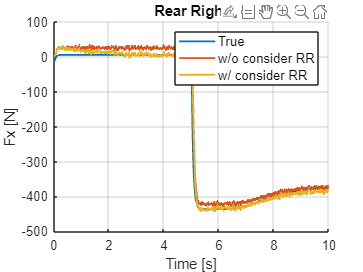

fx = Fx.data;
fx = reshape(fx,12,1269);
figure(100);clf;grid on;hold on;
plot(t,fx(4,:),'LineWidth',1.5);
plot(t,fx(8,:),'LineWidth',1.5);
plot(t,fx(12,:),'LineWidth',1.5);
xlim([0 10]);xlabel("Time [s]");
ylabel("Fx [N]");
title("Rear Right")
legend("True","w/o consider RR","w/ consider RR","fontsize",11);
set(gca,"Fontsize",11);

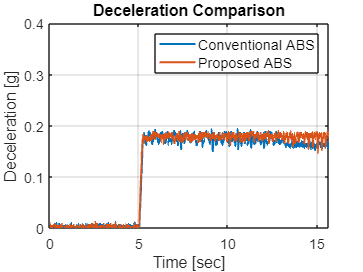

ax_pro = a_x.Data;
ax_conv = Ax.data;
n = length(ax_pro);
t = 0:0.01:0.01*(n-1);
figure(1); clf;
plot(t(1:n),-ax_conv(1:n)/9.8,'LineWidth',1.5);grid on;hold on;
plot(t(1:n),-ax_pro(1:n)/9.8,'LineWidth',1.5);
title("Deceleration Comparison");
legend("Conventional ABS","Proposed ABS","Fontsize",12);xlabel("Time [sec]");ylabel("Deceleration [g]");
set(gca,"Fontsize",12); ylim([0 0.4])

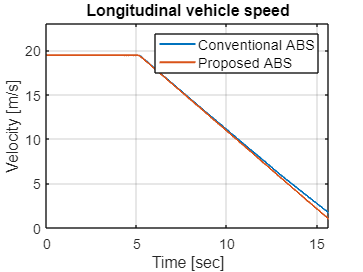

vx_pro = V_car.Data;
vx_conv = Vcar.data;
figure(2); clf;
plot(t(1:n),vx_conv(1:n),'LineWidth',1.5);grid on;hold on;
plot(t(1:n),vx_pro(1:n),'LineWidth',1.5);
title("Longitudinal vehicle speed");
legend("Conventional ABS","Proposed ABS","Fontsize",12);xlabel("Time [sec]");ylabel("Velocity [m/s]");
set(gca,"Fontsize",12); ylim([0 23])

jerk_conv = (-ax_conv(501:n-50)+ax_conv(500:n-51))*100;
jerk_pro = (-ax_pro(501:n-50)/9.8+ax_pro(500:n-51)/9.8)*100;
jerk_conv = abs(jerk_conv);
jerk_pro = abs(jerk_pro);
disp(mean(ax_conv(500:n))/9.8);

   -0.1695



disp(mean(ax_pro(500:n))/9.8);

   -0.1760



disp(mean(jerk_conv));

    3.8073



disp(mean(jerk_pro));

    0.4074



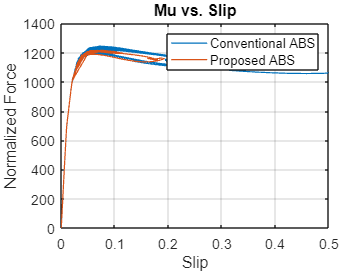

Fxr = F_x.data;
Fzr = F_z.data;
Fxrc = Fx.data;
Fzrc = Fz.data;
lambda = slip.data;
lambdac = Slip.data;
figure(3); clf;
plot(lambdac(:,3),Fxrc(:,3),'LineWidth',1);grid on;hold on;
plot(lambda(:,3),Fxr(:,3),'LineWidth',1);

title("Mu vs. Slip");legend("Conventional ABS","Proposed ABS")
xlabel("Slip");ylabel("Normalized Force");
set(gca,"Fontsize",12); xlim([0 0.5]);

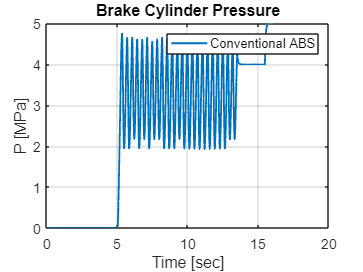


p = Pmc.data;
nc = length(p);
tc = 0:0.01:0.01*(nc-1);
figure(4); clf;
plot(tc,p,'LineWidth',1.5);grid on;
title("Brake Cylinder Pressure");legend("Conventional ABS")
xlabel("Time [sec]");ylabel("P [MPa]");
set(gca,"Fontsize",12);

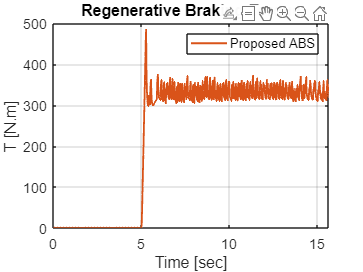


tq = T_b.data;
figure(5); clf;
plot(t,-tq,'LineWidth',1.5,'Color','#D95319');grid on;
title("Regenerative Braking Torque");legend("Proposed ABS")
xlabel("Time [sec]");ylabel("T [N.m]");
set(gca,"Fontsize",12);

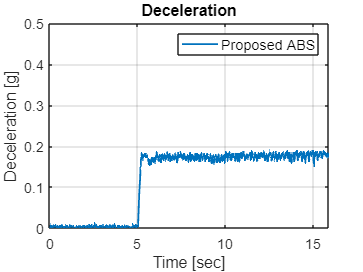

ax_pro = a_x.Data;
n = length(ax_pro);
t = 0:0.01:0.01*(n-1);
figure(1); clf;
plot(t(1:n),-ax_pro(1:n)/9.8,'LineWidth',1.5);grid on;hold on;
title("Deceleration");
legend("Proposed ABS","Fontsize",12);xlabel("Time [sec]");ylabel("Deceleration [g]");
set(gca,"Fontsize",12); ylim([0 0.5])

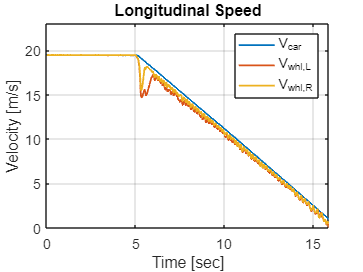

vx_pro = V_car.Data;
vwhl = V_whl.Data;
figure(2); clf;
plot(t(1:n),vx_pro(1:n),'LineWidth',1.5);grid on;hold on;
plot(t(1:n),vwhl(1:n,3),'LineWidth',1.5);
plot(t(1:n),vwhl(1:n,4),'LineWidth',1.5);
title("Longitudinal Speed");
legend("V_{car}","V_{whl,L}","V_{whl,R}","Fontsize",12);xlabel("Time [sec]");ylabel("Velocity [m/s]");
set(gca,"Fontsize",12); ylim([0 23])

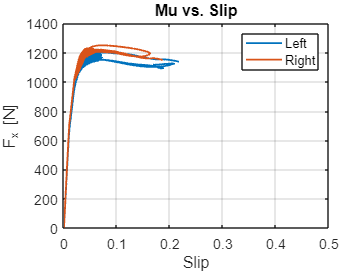


Fxr = F_x.data;
Fzr = F_z.data;
lambda = slip.data;
figure(3); clf;
plot(lambda(:,3),Fxr(:,3),'LineWidth',1.5);grid on;hold on;
plot(lambda(:,4),Fxr(:,4),'LineWidth',1.5);grid on;hold on;
title("Mu vs. Slip");legend("Left","Right")
xlabel("Slip");ylabel("F_x [N]");
set(gca,"Fontsize",12); xlim([0 0.5]);

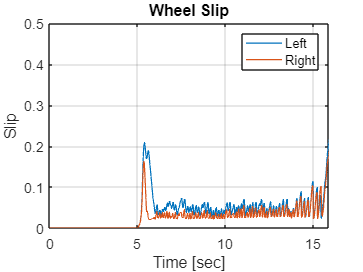

figure(4); clf;
plot(t,lambda(:,3),'LineWidth',1);grid on;hold on;
plot(t,lambda(:,4),'LineWidth',1);
title("Wheel Slip");legend("Left","Right")
xlabel("Time [sec]");ylabel("Slip");
set(gca,"Fontsize",12); ylim([0 0.5]);

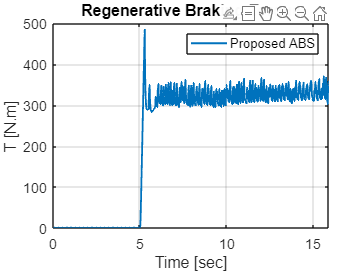


tq = T_b.data;
figure(5); clf;
plot(t,-tq,'LineWidth',1.5);grid on;
title("Regenerative Braking Torque");legend("Proposed ABS")
xlabel("Time [sec]");ylabel("T [N.m]");
set(gca,"Fontsize",12);

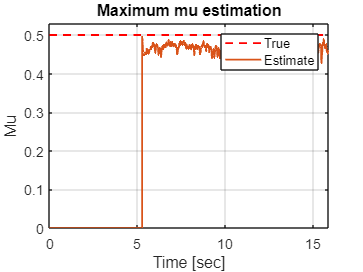


Mu = mu_est.data;
figure(6); clf;
ref = 0.5*ones(n,1);%ref(1:642) = 0.9;
plot(t,ref,'--r','LineWidth',1.5);grid on; hold on;
plot(t,Mu,'LineWidth',1.5);
title("Maximum mu estimation");legend("True","Estimate")
xlabel("Time [sec]");ylabel("Mu"); ylim([0 0.53])
set(gca,"Fontsize",12);